clear
clc

load('sizing')

%parameters from poster
W_S= 2973 %

W_S = 2973

C_cruise=295.1 %m/s

C_cruise = 295.1000

M_cruise=0.75

M_cruise = 0.7500

V_cruise=C_cruise*M_cruise %m/s

V_cruise = 221.3250

rho_cruise= 0.302748958

rho_cruise = 0.3027

W_cruise_W_total=0.842

W_cruise_W_total = 0.8420

Max_takeoff_weight=3740 %kg

Max_takeoff_weight = 3740

%mu_cruise=2.969*10^(-7)
mu_cruise=1.45*10^(-5)

mu_cruise = 1.4500e-05

character_c=0.6096

character_c = 0.6096

CL_design_cruise=( (W_cruise_W_total)*(W_S) )/ (0.5*rho_cruise*V_cruise^2)

CL_design_cruise = 0.3376


% L_over_D=Cl/cd;
% plot( Alpha, Cl)
% ylabel('Cl')
% xlabel('alpha')
% [CL_Alpha_curve, gof] = CL_ALPHA_FIT(Alpha, Cl)
% 
% Cl_design=CL_Alpha_curve(4.25)



% Cl_max=max(Cl)



%mach
sweep_25=22.221

sweep_25 = 22.2210

M_DD=0.7438

M_DD = 0.7438

M_DD_Eff=M_DD*sqrt(cosd(sweep_25))

M_DD_Eff = 0.7156

AR=7.8

AR = 7.8000

x=cosd(22)

x = 0.9272


Cl_design_a=(CL_design_cruise/(0.9*0.95))/cosd(sweep_25)

Cl_design_a = 0.4265



Km=1.05

Km = 1.0500


%lambda_opt=0.45*(0.85)^(-0.036*sweep_angle)
lambda_opt=0.45*exp(-0.036*sweep_25)

lambda_opt = 0.2022

lambda_min=0.2*(AR)^(0.25)*(cosd(sweep_25)^2)

lambda_min = 0.2864

SP=(Max_takeoff_weight*9.8)/(W_S) 

SP = 12.3283

mainwing.b = sqrt(AR*SP) 

mainwing = struct with fields:
    b: 9.8062



lambda=lambda_min

lambda = 0.2864


mainwing.Croot= (2*12.34086)/(9.811*(1+lambda))

mainwing = struct with fields:
        b: 9.8062
    Croot: 1.9556


mainwing.Ctip=lambda*mainwing.Croot

mainwing = struct with fields:
        b: 9.8062
    Croot: 1.9556
     Ctip: 0.5601


C_mean=(2/3) * mainwing.Croot* ((1+lambda+lambda^2)/(1+lambda))

C_mean = 1.3869


%c_dist
m=(0-mainwing.b/2)/(mainwing.Croot/mainwing.Ctip)

m = -1.4044


y_bar=(mainwing.b/6)*((1+2*lambda)/(1+lambda))

y_bar = 1.9983


t_c= 0.3*cosd(sweep_25)*((1-((5+M_DD_Eff^2)/(5+(Km-0.25*Cl_design_a)^2))^3.5)*((sqrt(1-M_DD_Eff^2)/M_DD_Eff^2)))^(2/3)

t_c = 0.1195


Re= (rho_cruise * V_cruise * C_mean )/ mu_cruise

Re = 6.4088e+06

twist=-3

twist = -3


[mainwing.sweepLE] = sweep_angle(sweep_25,0,25,AR,lambda)

mainwing = struct with fields:
          b: 9.8062
      Croot: 1.9556
       Ctip: 0.5601
    sweepLE: 25.6239




% i_w_mac=1
% i_w= (y_bar/(b/2))*twist*(x_position) + i_w_mac
alpha_0=-3

alpha_0 = -3

CL_cruise=0.4809

CL_cruise = 0.4809


Cl_alpha=(1.6-0.4)/((16*(pi/180)--0*(pi/180))) %issue find clalpha

Cl_alpha = 4.2972

i_w= (CL_cruise/Cl_alpha)+alpha_0 +0.4*twist

i_w = -4.0881


i_mac=1

i_mac = 1

x_span=[0:mainwing.b/2];
span_twist=((twist)/(mainwing.b/2))*x_span +i_mac+1.20939

span_twist =     2.2094    1.5975    0.9857    0.3738   -0.2381


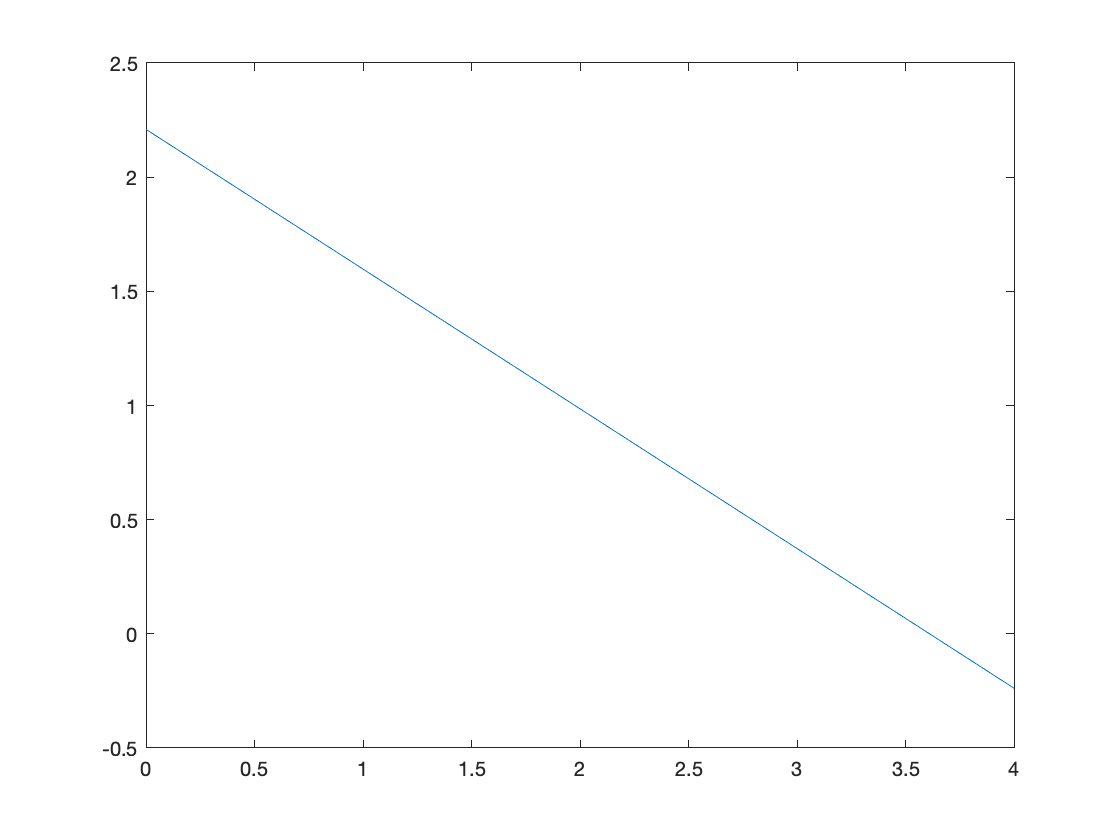

figure
plot(x_span,span_twist)


i_w_method=((twist*y_bar)/(mainwing.b/2)) +i_mac+1.20939

i_w_method = 0.9867

CLmax=1.6

CLmax = 1.6000

CLmax_eff=0.9*CLmax*cosd(sweep_25)

CLmax_eff = 1.3331

delta_y=19.3*t_c %for 65 series

delta_y = 2.3071


CLmax_takeooff = 1.9

CLmax_takeooff = 1.9000

Clmax_landing = 2.4

Clmax_landing = 2.4000

if CLmax_takeooff<Clmax_landing
    q=Clmax_landing
else
    q=CLmax_takeooff
end

q = 2.4000

%need 1.0669

%30% of the wing must be allocated to aileron placement for sufficient controllability

m=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)

m = -0.2846

m2=mainwing.sweepLE*(pi/180)

m2 = 0.4472

mainwing.HDL_PERC=0.60

mainwing = struct with fields:
           b: 9.8062
       Croot: 1.9556
        Ctip: 0.5601
     sweepLE: 25.6239
    HDL_PERC: 0.6000


mainwing.HDL_Croot=(1-mainwing.HDL_PERC)*mainwing.Croot

mainwing = struct with fields:
            b: 9.8062
        Croot: 1.9556
         Ctip: 0.5601
      sweepLE: 25.6239
     HDL_PERC: 0.6000
    HDL_Croot: 0.7822


mainwing.HDL_Ctip=(1-mainwing.HDL_PERC)*mainwing.Ctip

mainwing = struct with fields:
            b: 9.8062
        Croot: 1.9556
         Ctip: 0.5601
      sweepLE: 25.6239
     HDL_PERC: 0.6000
    HDL_Croot: 0.7822
     HDL_Ctip: 0.2241


[mainwing.sweepHDL]= sweep_angle(sweep_25,mainwing.HDL_PERC*100,25,AR,lambda)

mainwing = struct with fields:
            b: 9.8062
        Croot: 1.9556
         Ctip: 0.5601
      sweepLE: 25.6239
     HDL_PERC: 0.6000
    HDL_Croot: 0.7822
     HDL_Ctip: 0.2241
     sweepHDL: 17.1691


[fig] = horizontal_stab_plot(mainwing)

fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [617 599 560 420]
       Units: 'pixels'

  Show all properties


rhs_wing =          0         0
         0    1.9556
    4.9031   -0.3961
    4.9031   -0.9562
         0         0


lhs_wing =          0         0
         0    1.9556
   -4.9031   -0.3961
   -4.9031   -0.9562
         0         0


fig =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [617 599 560 420]
       Units: 'pixels'

  Show all properties


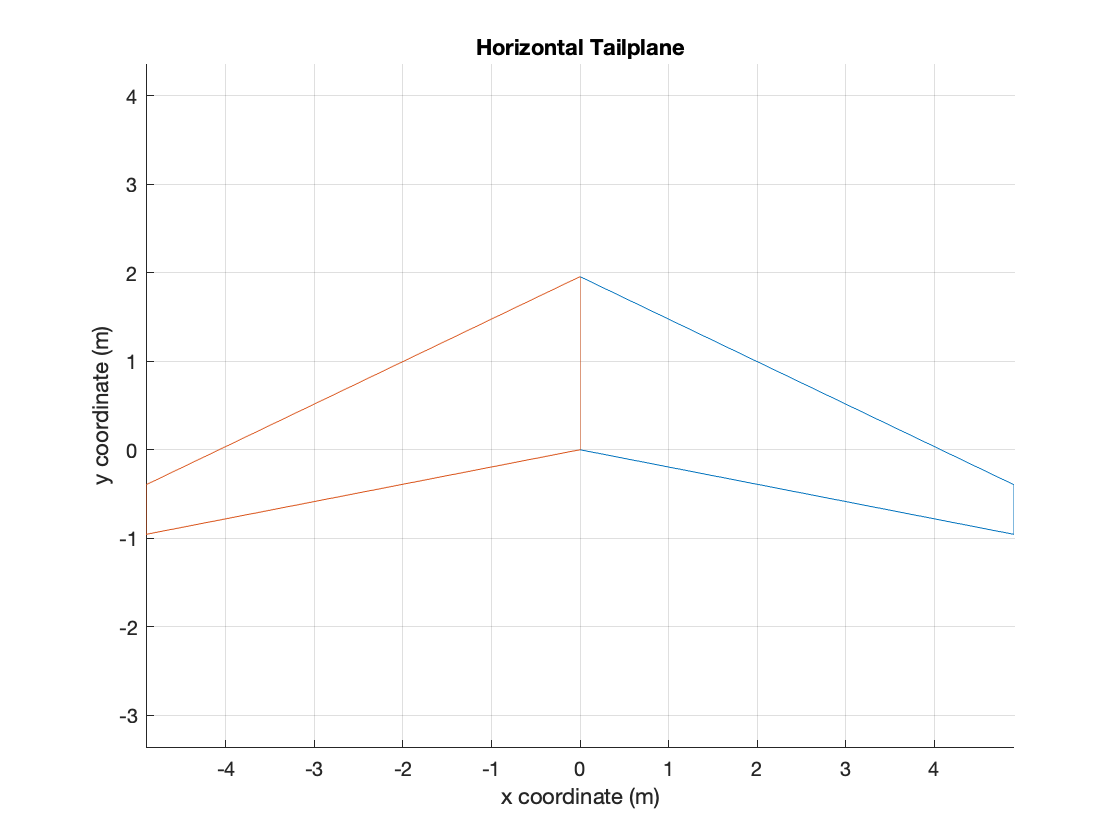

hold on

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [617 599 560 420]
       Units: 'pixels'

  Show all properties


rhs_wing =          0         0
         0    1.9556
    4.9031   -0.3961
    4.9031   -0.9562
         0         0


lhs_wing =          0         0
         0    1.9556
   -4.9031   -0.3961
   -4.9031   -0.9562
         0         0


rhs_wing_hdl =          0         0
         0    0.7822
    4.9031   -0.7326
    4.9031   -0.9567
         0         0


lhs_wing_hdl =          0         0
         0    0.7822
   -4.9031   -0.7326
   -4.9031   -0.9567
         0         0


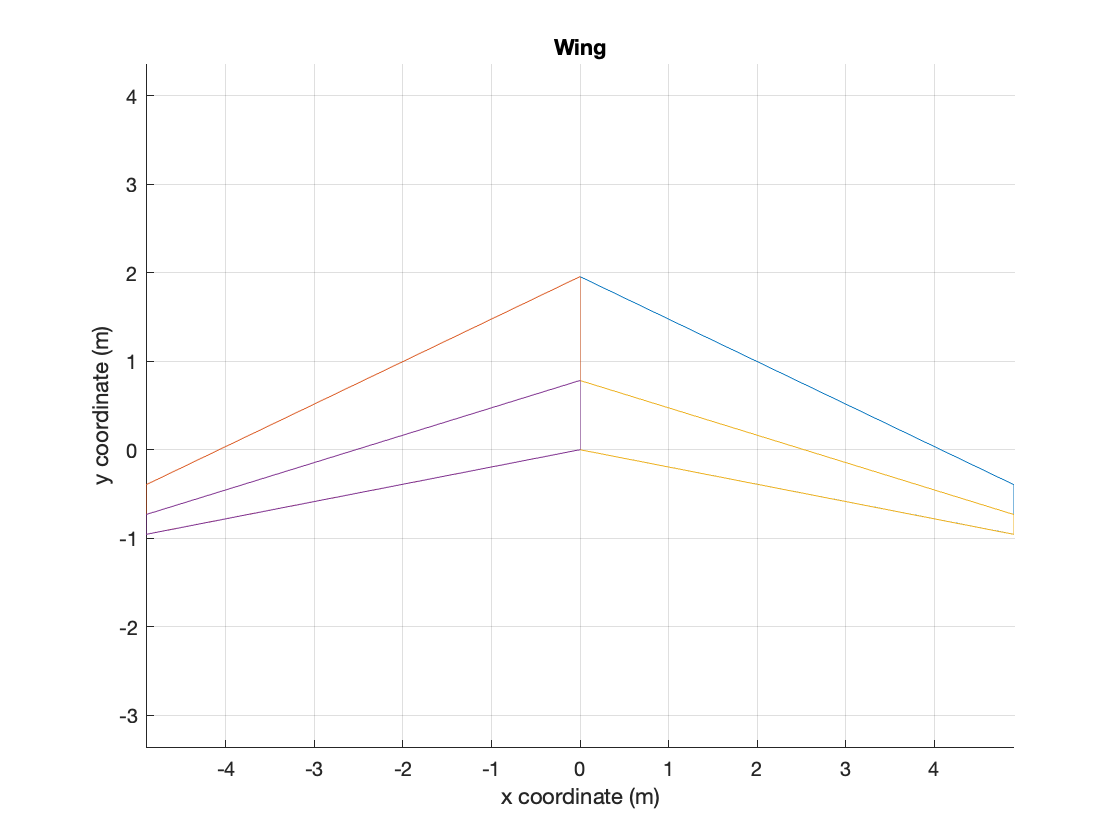

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [617 599 560 420]
       Units: 'pixels'

  Show all properties


[fig] = hdl(mainwing)


sref=((mainwing.Croot-mainwing.Ctip)/2)*mainwing.b
sflapped=(((mainwing.HDL_Croot-mainwing.HDL_Ctip)/2)*mainwing.b) - saileron

x_dist=[0:mainwing.b/2]

x_dist =      0     1     2     3     4


chord_dist=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*x_dist +mainwing.Croot

chord_dist =     1.9556    1.6710    1.3864    1.1018    0.8172


delta_CL=q-CLmax_eff

delta_Cl = 1.0669

delta_Cl=1.3*((c_dash)/chord_dist)
%delta_Cl_eff=0.9*delta_Cl*(sflapped/sref)*cos(sweep_HDL)
%CLeff is the 1.0669, delta_cl = 1.3cdash/c then find the other in terms of
%cf
delta_CL=0.9*delta_Cl*(sflapped/sref)*cosd(mainwing.sweepHDL)
%s_exposed=
%s_wet=s_exposed*(1.977+0.52(t_c))
% 
% save('wing','wing.mat')


